%% Shaft safety factor workings
% Method based on Shigley's Mechanical Engineering Design workflow
% Continuous shaft on 5 bearings, 4 gears, central point load in each span

clear; clc; close all;

%% -----------------------------
% 1. Inputs
% ------------------------------

g       = 9.81;          % m/s^2
m       = 6.0;           % kg, total mattress mass
m_g = 0.0784;            % kg, gear mass

m_g = 0.0784

nShafts = 2;
nGearsPerShaft = 4;
nAng = 20;
hAng = 30;

L       = 0.047;         % m, bearing span
dr      = 6.47e-3;       % m, thread root diameter
rp      = 17e-3;         % m, gear pitch radius

Sut     = 515;           % MPa, ultimate tensile strength, AISI 304
Sy      = 205;           % MPa, yield strength, AISI 304

Kt      = 2.8;           % theoretical stress concentration factor
q       = 0.5;           % notch sensitivity
Kf      = 1 + q*(Kt - 1);
Kfs     = Kf;            % cautious placeholder for torsional fatigue factor

% Marin factors
ka = 4.51 * Sut^(-0.265);       % machined/cold-drawn surface factor, MPa basis
kb = 1.24 * (dr*1e3)^(-0.107);  % size factor, diameter in mm
kc = 1.0;                       % bending
kd = 1.0;                       % room/body temperature approximation
ke = 0.753;                     % 99.9% reliability
kf_misc = 1.0;

Se_prime = 0.5 * Sut;           % MPa
Se = ka * kb * kc * kd * ke * kf_misc * Se_prime;

%% -----------------------------
% 2. Gear load
% ------------------------------
P = m_g + m*g/(nShafts*nGearsPerShaft) ;   % N per gear
loadPerShaft = nGearsPerShaft * P;    % N

fprintf('P per gear = %.4f N\n', P);

P per gear = 7.4359 N


fprintf('Load per shaft = %.4f N\n\n', loadPerShaft);

Load per shaft = 29.7436 N




%% -----------------------------
% 3. Continuous beam: three-moment theorem
% ------------------------------
% 5 bearings -> 4 spans.
% End bearing moments are zero: M1 = M5 = 0.
% For equal spans and central point load:
% M_{i-1} + 4*M_i + M_{i+1} = -0.75*P*L

nSpans = 4;
nSupports = nSpans + 1;
nInternal = nSupports - 2;

A = zeros(nInternal);
b = -0.75 * P * L * ones(nInternal,1);

for i = 1:nInternal
    A(i,i) = 4;
    if i > 1
        A(i,i-1) = 1;
    end
    if i < nInternal
        A(i,i+1) = 1;
    end
end

M_internal = A\b;                 % moments at B2, B3, B4
M_support = [0; M_internal; 0];   % moments at B1...B5

fprintf('Support moments, N.m:\n');

Support moments, N.m:


for i = 1:nSupports
    fprintf('B%d: %+ .6f N.m\n', i, M_support(i));
end

B1: +0.000000 N.m
B2: -0.056168 N.m
B3: -0.037445 N.m
B4: -0.056168 N.m
B5: +0.000000 N.m


fprintf('\n');

%% -----------------------------
% 4. Mid-span bending moments
% ------------------------------
% M_mid = P*L/4 + average of adjacent end moments

M_free_mid = P*L/4;
M_mid = zeros(nSpans,1);

for i = 1:nSpans
    M_mid(i) = M_free_mid + 0.5*(M_support(i) + M_support(i+1));
end

fprintf('Mid-span bending moments, N.m:\n');

Mid-span bending moments, N.m:


for i = 1:nSpans
    fprintf('Span %d: %+ .6f N.m\n', i, M_mid(i));
end

Span 1: +0.059288 N.m
Span 2: +0.040565 N.m
Span 3: +0.040565 N.m
Span 4: +0.059288 N.m


fprintf('\n');

% Maximum vertical bending moment
My_max = max(abs([M_support; M_mid]));

% If no horizontal gear forces are present:
Mz_max = 0;

% Combined bending moment
Mb = hypot(My_max, Mz_max);

fprintf('Maximum vertical bending moment My,max = %.6f N.m\n', My_max);

Maximum vertical bending moment My,max = 0.059288 N.m


fprintf('Maximum combined bending moment Mb = %.6f N.m\n\n', Mb);

Maximum combined bending moment Mb = 0.059288 N.m




%% -----------------------------
% 5. Bearing reactions check
% ------------------------------
% For each span:
% R_left = P/2 + (M_right - M_left)/L
% R_right = P - R_left

R_left_span = zeros(nSpans,1);
R_right_span = zeros(nSpans,1);
R_bearing = zeros(nSupports,1);

for i = 1:nSpans
    M_left = M_support(i);
    M_right = M_support(i+1);

    R_left_span(i) = P/2 + (M_right - M_left)/L;
    R_right_span(i) = P - R_left_span(i);

    R_bearing(i) = R_bearing(i) + R_left_span(i);
    R_bearing(i+1) = R_bearing(i+1) + R_right_span(i);
end

fprintf('Bearing reactions:\n');

Bearing reactions:


for i = 1:nSupports
    fprintf('B%d: %.4f N = %.4f P\n', i, R_bearing(i), R_bearing(i)/P);
end

B1: 2.5229 N = 0.3393 P
B2: 9.0293 N = 1.2143 P
B3: 6.6392 N = 0.8929 P
B4: 9.0293 N = 1.2143 P
B5: 2.5229 N = 0.3393 P


fprintf('Sum of reactions = %.4f N, expected = %.4f N\n\n', ...
    sum(R_bearing), loadPerShaft);

Sum of reactions = 29.7436 N, expected = 29.7436 N




%% -----------------------------
% 6. Torque cases
% ------------------------------
% Gear tooth force at pitch radius gives torque, not bending moment.
% One gear torque: T = P*rp
% All four gears torque: T = 4*P*rp

T_cases = [0;
           P*rp;
           4*P*rp];

caseNames = ["No torque";
             "One gear torque";
             "All four gears torque"];

%% -----------------------------
% 7. Section properties and stresses
% ------------------------------

Z_bending = pi*dr^3/32;   % m^3, bending section modulus
Z_torsion = pi*dr^3/16;   % m^3, torsional shear section modulus

sigma_b = Mb / Z_bending / 1e6;   % MPa

fprintf('Bending section modulus pi*d^3/32 = %.4e m^3\n', Z_bending);

Bending section modulus pi*d^3/32 = 2.6590e-08 m^3


fprintf('Torsion section modulus pi*d^3/16 = %.4e m^3\n', Z_torsion);

Torsion section modulus pi*d^3/16 = 5.3179e-08 m^3


fprintf('Bending stress sigma_b = %.4f MPa\n\n', sigma_b);

Bending stress sigma_b = 2.2297 MPa




%% -----------------------------
% 8. Static and fatigue safety factors
% ------------------------------

nCases = length(T_cases);

tau = zeros(nCases,1);
sigma_vm = zeros(nCases,1);
ny_vonMises = zeros(nCases,1);
Te = zeros(nCases,1);
tau_max_Tresca = zeros(nCases,1);
ny_Tresca = zeros(nCases,1);
sigma_a = zeros(nCases,1);
sigma_m_prime = zeros(nCases,1);
nf_Goodman = zeros(nCases,1);

for i = 1:nCases

    T = T_cases(i);

    % Torsional shear stress
    tau(i) = T / Z_torsion / 1e6;   % MPa

    % Static von Mises
    sigma_vm(i) = sqrt(sigma_b^2 + 3*tau(i)^2);
    ny_vonMises(i) = Sy / sigma_vm(i);

    % Static Tresca using equivalent torque
    Te(i) = sqrt(Mb^2 + T^2);
    tau_max_Tresca(i) = 16*Te(i)/(pi*dr^3)/1e6;   % MPa
    ny_Tresca(i) = (Sy/2) / tau_max_Tresca(i);

    % Fatigue: rotating shaft under fixed gravity load
    % Bending is fully reversed: alternating stress
    % Torque is steady: mean stress
    sigma_a(i) = Kf * sigma_b;
    sigma_m_prime(i) = sqrt(3) * Kfs * tau(i);

    nf_Goodman(i) = 1 / (sigma_a(i)/Se + sigma_m_prime(i)/Sut);

end

%% -----------------------------
% 9. Results table
% ------------------------------

Results = table( ...
    caseNames, ...
    T_cases, ...
    repmat(Mb,nCases,1), ...
    repmat(sigma_b,nCases,1), ...
    tau, ...
    sigma_vm, ...
    ny_vonMises, ...
    ny_Tresca, ...
    nf_Goodman, ...
    'VariableNames', { ...
    'Case', ...
    'Torque_Nm', ...
    'Mb_Nm', ...
    'SigmaB_MPa', ...
    'Tau_MPa', ...
    'SigmaVM_MPa', ...
    'ny_vonMises', ...
    'ny_Tresca', ...
    'nf_Goodman'});

disp(Results);

             Case              Torque_Nm     Mb_Nm      SigmaB_MPa    Tau_MPa    SigmaVM_MPa    ny_vonMises    ny_Tresca    nf_Goodman
    _______________________    _________    ________    __________    _______    ___________    ___________    _________    __________

    "No torque"                       0     0.059288      2.2297           0       2.2297         91.939        91.939        40.065  
    "One gear torque"           0.12641     0.059288      2.2297      2.3771       4.6822         43.783         39.04        24.907  
    "All four gears torque"     0.50564     0.059288      2.2297      9.5082       16.619         12.335        10.707        11.666  




fprintf('\nCorrected endurance limit Se = %.2f MPa\n', Se);


Corrected endurance limit Se = 169.74 MPa


fprintf('Fatigue stress concentration factor Kf = %.2f\n', Kf);

Fatigue stress concentration factor Kf = 1.90


fprintf('Torsional fatigue factor Kfs = %.2f\n\n', Kfs);

Torsional fatigue factor Kfs = 1.90



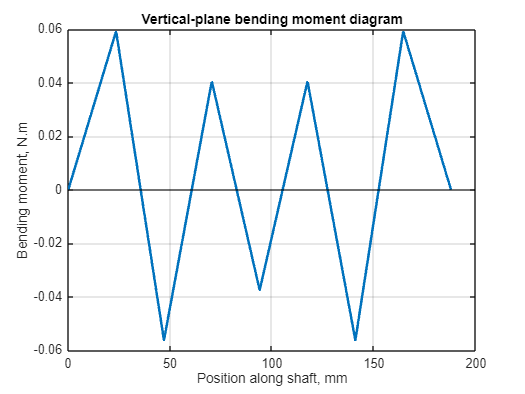


%% -----------------------------
% 10. Plot bending moment diagram
% ------------------------------

xAll = [];
MAll = [];

for i = 1:nSpans

    xloc = linspace(0,L,200).';

    % Simply-supported/free bending moment from central point load
    Mfree = zeros(size(xloc));

    leftHalf = xloc <= L/2;
    rightHalf = xloc > L/2;

    Mfree(leftHalf) = (P/2) .* xloc(leftHalf);
    Mfree(rightHalf) = (P/2) .* (L - xloc(rightHalf));

    % Add end-moment line between supports
    MendLine = M_support(i)*(1 - xloc/L) + M_support(i+1)*(xloc/L);

    Mspan = Mfree + MendLine;
    xglob = (i-1)*L + xloc;

    xAll = [xAll; xglob];
    MAll = [MAll; Mspan];

end

figure;
plot(xAll*1000, MAll, 'LineWidth', 2);
grid on;
xlabel('Position along shaft, mm');
ylabel('Bending moment, N.m');
title('Vertical-plane bending moment diagram');
yline(0,'k-');


%% -----------------------------
% 11. Optional thesis comparison
% ------------------------------
% Independent simply-supported span moment:
M_simple = P*L/4;

% Incorrect offset-as-bending value:
M_offset_wrong = P*rp;
M_wrong_combined = hypot(M_simple, M_offset_wrong);

fprintf('Independent simply-supported PL/4 moment = %.6f N.m\n', M_simple);

Independent simply-supported PL/4 moment = 0.087372 N.m


fprintf('Incorrect offset-as-bending value P*rp = %.6f N.m\n', M_offset_wrong);

Incorrect offset-as-bending value P*rp = 0.126410 N.m


fprintf('Incorrect combined bending estimate = %.6f N.m\n', M_wrong_combined);

Incorrect combined bending estimate = 0.153667 N.m
